## Parte I

% Read file data
cal_data = readtable("data/cal.csv");

% Expand summary calibration data 
clf;
temps = zeros(15,1);
tens  = zeros(15, 1);
desl  = zeros(15, 1);

temps(1:5)  = 20;
temps(6: 10) = 30;
temps(11: 15) = 40;

tens(1:5) = cal_data.Tens_o_V__20_C;
tens(6:10) = cal_data.Tens_o_V__30_C;
tens(11:15) = cal_data.Tens_o_V__40_C;

desl(1:5) = cal_data.Deslocamento__m_;
desl(6:10) = cal_data.Deslocamento__m_;
desl(11:15) = cal_data.Deslocamento__m_;

% Scatter plot the calibration data
[temps tens desl]

ans =    20.0000         0         0
   20.0000    0.3200    2.5000
   20.0000    0.6500    5.0000
   20.0000    0.9800    7.5000
   20.0000    1.3000   10.0000
   30.0000         0         0
   30.0000    0.7300    2.5000
   30.0000    1.4500    5.0000
   30.0000    2.1800    7.5000
   30.0000    2.9000   10.0000


% stem3(temps, tens, desl), hold on;

% Fit the calibration surface and plot
F = fit([temps desl], tens, 'poly23')

     Linear model Poly23:
     F(x,y) = p00 + p10*x + p01*y + p20*x^2 + p11*x*y + p02*y^2 + p21*x^2*y +
                     p12*x*y^2 + p03*y^3
     Coefficients (with 95% confidence bounds):
       p00 =    -0.02014  (-0.09018, 0.04989)
       p10 =    0.001329  (-0.003582, 0.006239)
       p01 =     -0.1305  (-0.1451, -0.1159)
       p20 =      -2e-05  (-0.0001013, 6.129e-05)
       p11 =     0.01092  (0.01008, 0.01176)
       p02 =   0.0006286  (-0.0008597, 0.002117)
       p21 =    0.000102  (8.873e-05, 0.0001153)
       p12 =  -5.714e-06  (-3.162e-05, 2.019e-05)
       p03 =  -3.556e-05  (-0.000119, 4.788e-05)



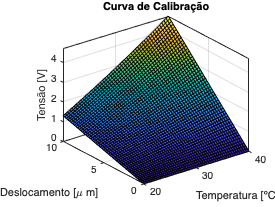

plot(F);
title('Curva de Calibração');
xlabel('Temperatura [ºC]'), ylabel('Deslocamento [\mu m]'), zlabel('Tensão [V]')

[theta_Temp, theta_Tens] = differentiate(F, [36.1131, 2.7197])

theta_Temp = -0.2711

theta_Tens = 2.2997


s_x = sqrt((theta_Temp.*s_Temp).^(2) + (theta_Tens.*s_Tens).^(2))

s_x = 0.1690

b_x = sqrt((theta_Temp.*b_ter).^(2) + (theta_Tens.*b_vol)^2)

b_x = 0.5053

u_x = sqrt(s_x + b_x)

u_x = 0.8211

u_x*tinv(0.975, 49)

ans = 1.6502

% Sensibilidades Estáticas
f_20c.p1

ans = 0.1304

f_30c.p1

ans = 0.2900

f_40c.p1

ans = 0.4700

## Parte II

% Read data file 
measured_values = readtable("data/Data05.csv");
measured_values.Properties.VariableNames = {'Num', 'Tens', 'Temp'}

measured_values = 50×3 table
    Num     Tens      Temp 
    ___    ______    ______

     1     2.4837    33.979
     2     1.8672    37.229
     3     2.7627    37.015
     4     2.8438    39.385
     5     2.1268    37.183
     6     3.2955    34.713
     7     3.2946    36.761
     8     2.6812    33.982
     9     2.8636    35.961
    10     2.7873    35.904
    11     2.6066        36
    12     3.0629    35.364
    13     2.4058     38.19
    14     3.7916    32.252
    15     2.6318    36.856
    16      2.757    37.791



% Uncertantisijsdfjlskdjf 
V_media = mean(measured_values.Tens)

V_media = 2.7197

T_media = mean(measured_values.Temp)

T_media = 36.1131

b_vol = V_media*2e-2

b_vol = 0.0544

b_ter = T_media*5e-2

b_ter = 1.8057


N = height(measured_values)

N = 50

s_Tens = std(measured_values.Tens) ./ sqrt(N)

s_Tens = 0.0690

s_Temp = std(measured_values.Temp) ./ sqrt(N)

s_Temp = 0.2138

b_total = sqrt(b_vol.^2 + b_ter.^2)

b_total = 1.8065

s_total = sqrt(s_Temp.^2 + s_Tens.^2)

s_total = 0.2246


u_total = tinv(0.975, N-1) .* sqrt(b_total.^2 + s_total.^2)

u_total = 3.6582

hold off; clf;
temps = zeros(15,1);
tens  = zeros(15, 1);
desl  = zeros(15, 1);

temps(1:5)  = 20;
temps(6: 10) = 30;
temps(11: 15) = 40;

tens(1:5) = cal_data.Tens_o_V__20_C;
tens(6:10) = cal_data.Tens_o_V__30_C;
tens(11:15) = cal_data.Tens_o_V__40_C;

desl(1:5) = cal_data.Deslocamento__m_;
desl(6:10) = cal_data.Deslocamento__m_;
desl(11:15) = cal_data.Deslocamento__m_;

[temps tens desl]

ans =    20.0000         0         0
   20.0000    0.3200    2.5000
   20.0000    0.6500    5.0000
   20.0000    0.9800    7.5000
   20.0000    1.3000   10.0000
   30.0000         0         0
   30.0000    0.7300    2.5000
   30.0000    1.4500    5.0000
   30.0000    2.1800    7.5000
   30.0000    2.9000   10.0000


stem3(temps, tens, desl), hold on;
F = scatteredInterpolant(tens, temps, desl);
new_point = F(2.7197, 36.1131)

new_point = 7.2738

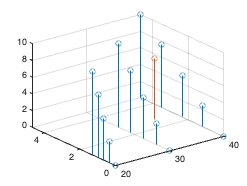

stem3( 36.1131, 2.7197, new_point);